inputs

func = @(x) x.^2 - 4.*x + 4 - log(x)

func = function_handle with value:
    @(x)x.^2-4.*x+4-log(x)



p0 = 1

p0 = 1

max_iter = 100

max_iter = 100


% tolerance
tol = 1e-5

tol = 1.0000e-05

symbolic derivatives

syms x
func_sym = func(x)

$$func\_sym = x^{2}-\log\left(x\right)-4\,x+4$$

dfunc_sym = diff(func_sym, x)

$$dfunc\_sym = 2\,x-\frac{1}{x}-4$$

derivative function

dfunc = matlabFunction(dfunc_sym, "Vars", x)

dfunc = function_handle with value:
    @(x)x.*2.0-1.0./x-4.0


% step 1
iter = 1

iter = 1


results = table()


results =

  0×0 empty table

	Get insights using Copilot



converged = false

converged = logical
   0


% step 2
while iter <= max_iter
    % step 3
    f_p0 = func(p0)
    df_p0 = dfunc(p0)
    p = p0 - f_p0./df_p0

    f_p = func(p)   % not necessary
    results(end+1,:) = table( ...
        iter, p0, p, f_p0, df_p0, f_p ...
    )

    % step 4
    if abs(p - p0) < tol
        converged = true
        break
    end

    % step 5
    iter = iter + 1

    % step 6
    p0 = p

end

f_p0 = 1

df_p0 = -3

p = 1.3333

f_p = 0.1568

results = 1×6 table
    iter    p0      p       f_p0    df_p0      f_p  
    ____    __    ______    ____    _____    _______

     1      1     1.3333     1       -3      0.15676

	Get insights using Copilot


iter = 2

p0 = 1.3333

f_p0 = 0.1568

df_p0 = -2.0833

p = 1.4086

f_p = 0.0072

results = 2×6 table
    iter      p0        p        f_p0       df_p0        f_p   
    ____    ______    ______    _______    _______    _________

     1           1    1.3333          1         -3      0.15676
     2      1.3333    1.4086    0.15676    -2.0833    0.0071969

	Get insights using Copilot


iter = 3

p0 = 1.4086

f_p0 = 0.0072

df_p0 = -1.8928

p = 1.4124

f_p = 1.8094e-05

results = 3×6 table
    iter      p0        p         f_p0        df_p0        f_p    
    ____    ______    ______    _________    _______    __________

     1           1    1.3333            1         -3       0.15676
     2      1.3333    1.4086      0.15676    -2.0833     0.0071969
     3      1.4086    1.4124    0.0071969    -1.8928    1.8094e-05

	Get insights using Copilot


iter = 4

p0 = 1.4124

f_p0 = 1.8094e-05

df_p0 = -1.8833

p = 1.4124

f_p = 1.1545e-10

results = 4×6 table
    iter      p0        p          f_p0        df_p0        f_p    
    ____    ______    ______    __________    _______    __________

     1           1    1.3333             1         -3       0.15676
     2      1.3333    1.4086       0.15676    -2.0833     0.0071969
     3      1.4086    1.4124     0.0071969    -1.8928    1.8094e-05
     4      1.4124    1.4124    1.8094e-05    -1.8833    1.1545e-10

	Get insights using Copilot


converged = logical
   1



if ~converged
    error("the method failed after %d iteration", max_iter)
end

disp(results)

    iter      p0        p          f_p0        df_p0        f_p    
    ____    ______    ______    __________    _______    __________

     1           1    1.3333             1         -3       0.15676
     2      1.3333    1.4086       0.15676    -2.0833     0.0071969
     3      1.4086    1.4124     0.0071969    -1.8928    1.8094e-05
     4      1.4124    1.4124    1.8094e-05    -1.8833    1.1545e-10



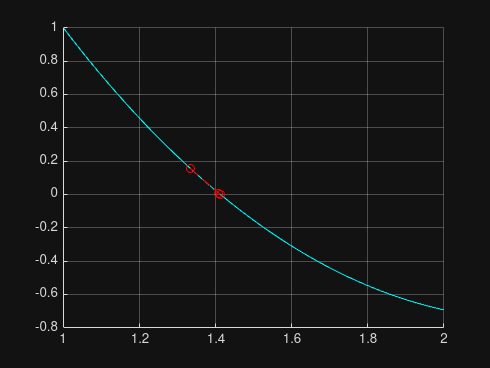

figure
hold on
fplot(func, [1, 2], 'c')
plot(results.p, results.f_p, 'r--o')
grid on
hold off